## Setup

close all
save_folder = 'truncated_3\';
save_suffix = '';

mkdir data\truncated_3

mkdir figures\truncated_3


filename = 'C:\Users\pyeung\Downloads\HighwayLong3.csv_10.10.10.143_17037.csv';
T = readtable(filename, 'PreserveVariableNames', true);

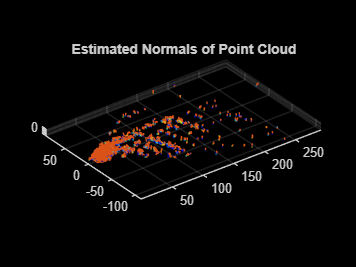

x = T.("x (m)");
y = T.("y (m)");
z = T.("z (m)");

x = x(z<1);
y = y(z<1);
z = z(z<1);

intens = T.intensity;
intens = intens(z<1);
xyz = [x, y, z];

writematrix(xyz,strcat('data\',save_folder,'coordinates.csv'))
pc = pointCloud(xyz, 'Intensity', intens(z<=1));

lower = min([pc.XLimits pc.YLimits]);
upper = max([pc.XLimits pc.YLimits]);

xlimits = [lower upper];
ylimits = [lower upper];
zlimits = pc.ZLimits;

inc = 1;

normals = pcnormals(pc);
x1 = pc.Location(1:inc:end,1);
y1 = pc.Location(1:inc:end,2);
z1 = pc.Location(1:inc:end,3);
u1 = normals(1:inc:end,1);
v1 = normals(1:inc:end,2);
w1 = normals(1:inc:end,3);

writematrix(normals,strcat('data\',save_folder,'normals.csv'));

figure
pcshow(pc)
title('Estimated Normals of Point Cloud')
hold on
quiver3(x1,y1,z1,u1,v1,w1);
hold off


writematrix([x1,y1,z1,u1,v1,w1], strcat('data\',save_folder,'origPc.csv'));

## Divide point cloud into cells

index = 1;
incx = 1;
incy = 1;
incz = 1;

r = zeros(size(x, 1),1);

for i = min(pc.XLimits)-1:incx:max(pc.XLimits)
    for j = min(pc.YLimits)-1:incy:max(pc.YLimits)
        for k = min(pc.ZLimits)-1:incz:max(pc.ZLimits)
            indices = x>i & x<=i+incx & y>j & y<=j+incy & z>k & z<=k+incz;
            %size(indices(indices==1))
            r(indices) = index;
            index = index + 1;
        end
    end
end

writematrix(r,strcat('data\',save_folder,'indices.csv'));
cmap = jet(index);

## Create new point cloud with averaged normals

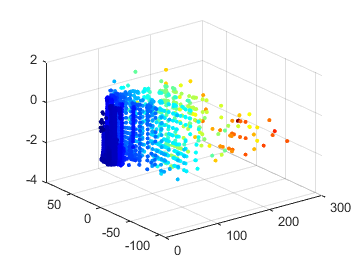

% New point cloud

newPoints = zeros(index,3);

for i = 1:index
    if size(x(r==i),1) > 0
        newPoints(i,1) = mean(x(r==i));
        newPoints(i,2) = mean(y(r==i));
        newPoints(i,3) = mean(z(r==i));
    end
end
figure(), scatter3(x,y,z,10,cmap(r,:),'filled')
saveas(gcf,strcat('figures\',save_folder,'scatterplot_new_pc.png'))

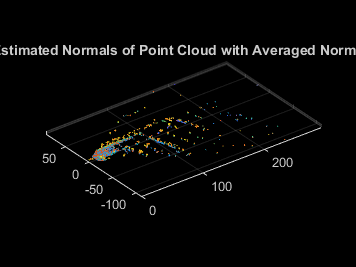


newPc = pointCloud(newPoints);

% New normals

newNormals = zeros(index, 3);

f = 1;

for i = 1:index
    if size(x(r==i),1) > 0
        newNormals(i,1) = f*mean(normals(r==i,1));
        newNormals(i,2) = f*mean(normals(r==i,2));
        newNormals(i,3) = f*mean(normals(r==i,3));
        newNormals(i,:) = newNormals(i,:)/norm(newNormals(i,:));
    end
end

x2 = newPc.Location(1:1:end,1);
y2 = newPc.Location(1:1:end,2);
z2 = newPc.Location(1:1:end,3);
u2 = newNormals(1:1:end,1);
v2 = newNormals(1:1:end,2);
w2 = newNormals(1:1:end,3);

writematrix(newNormals,strcat('data\',save_folder,'newNormals.csv'))

figure
pcshow(newPc)
title('Estimated Normals of Point Cloud with Averaged Normals')
hold on
quiver3(x2,y2,z2,u2,v2,w2);
hold off


arr = [x2,y2,z2,u2,v2,w2];

arr( ~any(arr,2), : ) = [];

writematrix(arr, strcat('data\',save_folder,'newPc.csv'));

## Scatterplot colored by z component of normal vector

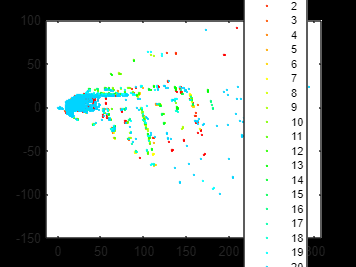

% Old point cloud

arr1 = [x1,y1,z1,u1,v1,w1];

colorvar = zeros(size(arr1,1),1);
index = 1;
inc2 = 0.1;

for i = -1:inc2:1
    colorvar(arr1(:,6) >= i & arr1(:,6) < i + inc2) = index;
    index = index + 1;
end

clr = hsv(length(unique(colorvar(:)))+16);

gscatter(arr1(:,1), arr1(:,2), colorvar(:), clr, '.')
saveas(gcf,strcat('figures\',save_folder,'scatter_orig_xy.png'))

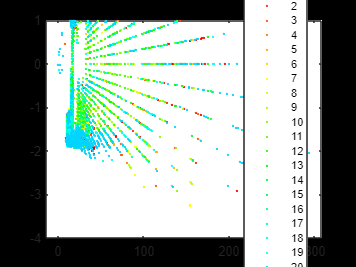


gscatter(arr1(:,1), arr1(:,3), colorvar(:), clr, '.')
saveas(gcf,strcat('figures\',save_folder,'scatter_orig_xz.png'))

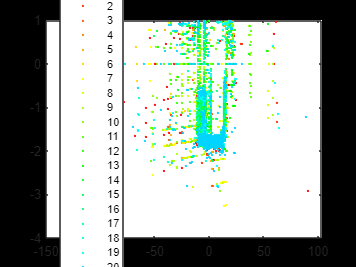


gscatter(arr1(:,2), arr1(:,3), colorvar(:), clr, '.')
saveas(gcf,strcat('figures\',save_folder,'scatter_orig_yz.png'))

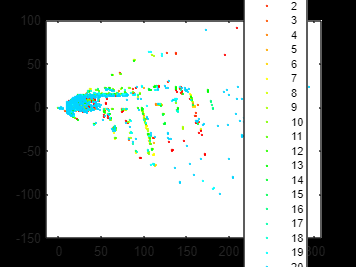


% New point cloud

arr2 = [x2,y2,z2,u2,v2,w2];

colorvar = zeros(size(arr2,1),1);
index = 1;


for i = -1:inc2:1
    colorvar(arr2(:,6) >= i & arr2(:,6) < i + inc2) = index;
    index = index + 1;
end

% clr = hsv(length(unique(colorvar(:)))+6);

gscatter(arr2(:,1), arr2(:,2), colorvar(:), clr, '.')
saveas(gcf,strcat('figures\',save_folder,'scatter_new_xy.png'))

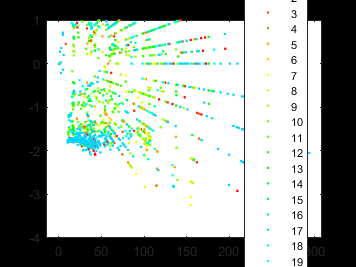


gscatter(arr2(:,1), arr2(:,3), colorvar(:), clr, '.')
saveas(gcf,strcat('figures\',save_folder,'scatter_new_xz.png'))

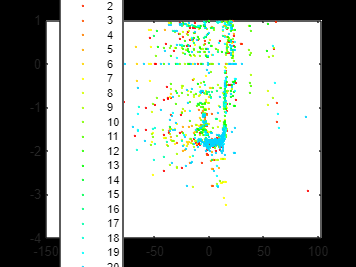


gscatter(arr2(:,2), arr2(:,3), colorvar(:), clr, '.')
saveas(gcf,strcat('figures\',save_folder,'scatter_new_yz.png'))